% we import the dataset
img_dataset = "C:\Users\USER\Documents\MATLAB\img_dataset";

files = dir(fullfile(img_dataset, '*.jpg'));
filenames = {files.name}';
filepaths = cellfun(@(s) fullfile(img_dataset, s), filenames, 'UniformOutput', false);

% we display length of list
disp(numel(filepaths));

    96



disp(filenames(1:5))

    {'1-01.JPG' }
    {'1-02.JPG' }
    {'1-03.JPG' }
    {'10-01.JPG'}
    {'10-02.JPG'}



labels = zeros(size(filenames));

% we assign labels based on filename endings
for i = 1:numel(filenames)
    if contains(filenames{i}, '-01')
        labels(i) = 1;  % Correctly exposed
    elseif contains(filenames{i}, '-02')
        labels(i) = 2;  % Overexposed
    elseif contains(filenames{i}, '-03')
        labels(i) = 3;  % Underexposed
    else
        warning('Filename %s does not match expected pattern.', filenames{i});
    end
end

### Image Classification

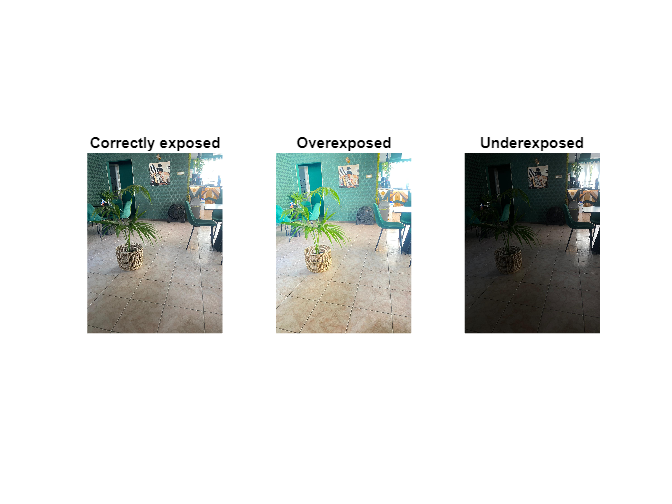

% we load the images
correct = imread("C:\Users\USER\Documents\MATLAB\img_dataset\18-01.JPG");
correct_img = im2double(correct);
underexposed = imread("C:\Users\USER\Documents\MATLAB\img_dataset\15-03.JPG");
underexposed_img = im2double(underexposed);
overexposed = imread("C:\Users\USER\Documents\MATLAB\img_dataset\14-02.JPG");
overexposed_img = im2double(overexposed);

% convert to YCbCr (to get luminance values from Y channel)
norm_ycbcr = rgb2ycbcr(correct_img);
low_ycbcr = rgb2ycbcr(underexposed_img);
high_ycbcr = rgb2ycbcr(overexposed_img);

% we get luminance values (Y channel)
lum_norm = norm_ycbcr(:, :, 1);
lum_low = low_ycbcr(:, :, 1);
lum_high = high_ycbcr(:, :, 1);


figure;
subplot(1, 3, 1), imshow(correct_img), title("Correctly exposed");
subplot(1, 3, 2), imshow(overexposed_img), title("Overexposed");
subplot(1, 3, 3), imshow(underexposed_img), title("Underexposed");

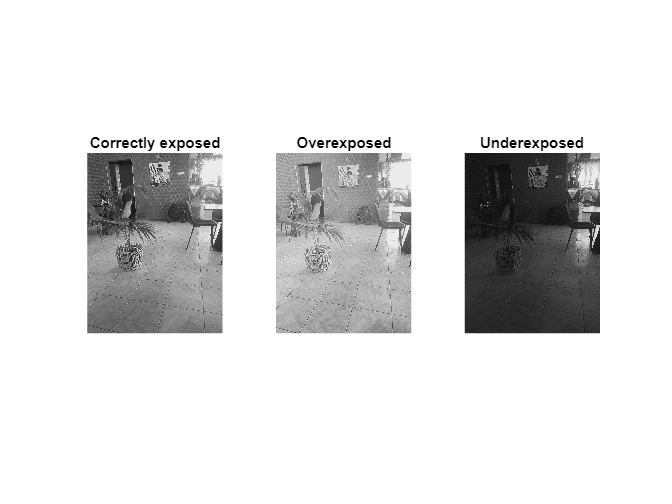

figure;
subplot(1, 3, 1), imshow(lum_norm), title("Correctly exposed");
subplot(1, 3, 2), imshow(lum_high), title("Overexposed");
subplot(1, 3, 3), imshow(lum_low), title("Underexposed");

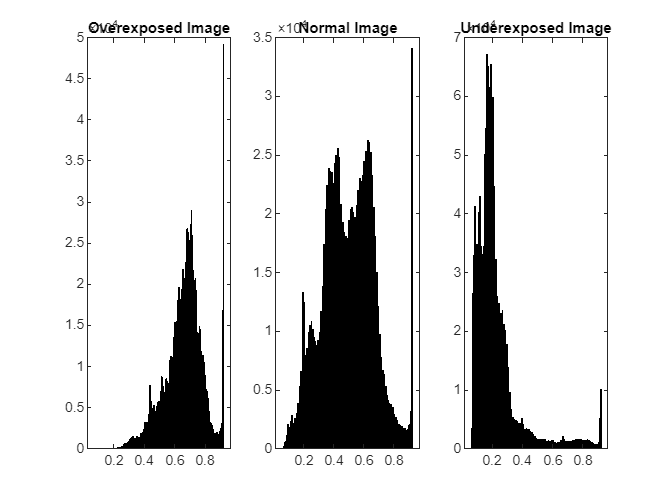

% we plot histograms
figure;
subplot(1, 3, 1), histogram(lum_high), title("Overexposed Image");
subplot(1, 3, 2), histogram(lum_norm), title("Normal Image");
subplot(1, 3, 3), histogram(lum_low), title("Underexposed Image");

disp(skewness(lum_norm, 0, [1, 2]));

    0.0955



 disp(skewness(lum_low, 0, [1, 2]));

    2.5274



  disp(skewness(lum_high, 0, [1, 2]))

   -0.3977



- **FEATURE EXTRACTION**

From now on we extract low-level features from images to obtain data that will be used to train the classifier. 

The chosen features are the mean, the variance and the skewness, that is, the first three moments of the distributions.

Moreover I chose to analyze contrast of images, an important feature which measures the difference between the maximum and minimum pixel intensities. A low contrast can be associated with both underexposed and overexposed images while high contrast is usually associated with a more balanced exposure.

Last but not least, I chose to add min max ranges of histogram pixels to have a deeper overview on how they are distributed.

features = extract_features(filepaths);

features = zscore(features)

features =     0.2795   -0.3859   -0.2355    0.3936   -0.5419   -0.4943
   -0.5900    0.8188    1.0635   -0.1473    0.8920    0.2506
   -0.9232    0.7244    0.3123    0.4570    0.1841   -0.4981
    0.1659    1.5425   -0.3798    0.4925   -0.2948   -0.3446
    0.9137   -0.4207   -0.4693    0.0351   -0.5451    0.3399
   -1.5111   -0.7632    1.6009    0.4805   -0.1497   -0.4978
    0.6099    0.4408   -1.1515    0.4925   -0.4377   -0.4624
    1.0870   -1.5223   -0.6456   -0.8985   -0.5453   -0.3801
   -1.2772   -1.3210   -0.3322    0.4833    1.0940   -0.4974
    0.5611   -0.0636   -1.1091    0.4925   -0.4740   -0.4907


- **DATASET CREATION AND PREPROCESSING**

We create the dataset concatenating all features previously extracted then, we perform a train-test split. I decided to follow the usual 80-20 % rule, 80% of the features will be used for training and what is left will be used for testing.

% dataset creation: features and target
 dataset = [features, labels];
 % shuffle to otain a random ordering
 dataset = dataset(randperm(size(dataset, 1)), :);
 % train-test split
 y_train = dataset(1:end-20, end);
 X_train = dataset(1:end-20, 1:end-1);
 y_test = dataset(end-19:end, end);
 X_test = dataset(end-19:end, 1:end-1);

We do a further preprocessing step by applying MinMax scaling on the features

 % take min and max values for train, and reuse them also for test
 min_vals = min(X_train, [], 1);
 max_vals = max(X_train, [], 1);
 %we save min and max train vals
 %save("train_min.mat", "min_vals");
 %save("train_max.mat", "max_vals");
 X_train = (X_train - min_vals)./(max_vals - min_vals);
 X_test = (X_test - min_vals)./(max_vals - min_vals)

X_test =     0.1893    0.1514    0.4994    0.4869    0.0649    0.0120
    0.8984    0.2140    0.0303    0.9856    0.0000    0.0050
   -0.0133    0.2743    1.0000    0.9551    0.2637         0
    0.4091    0.4775    0.3774    1.0000    0.0543    0.0121
    0.4018    0.7466    0.5245    1.0000    0.0103    0.0958
    0.1674    0.3744    0.4939    0.9984    0.1659    0.0001
    0.3206    0.7939    0.5366    1.0000    0.1522    0.1566
    0.6033    0.5279    0.2834    1.0000    0.0173    0.0031
    0.3165    0.4045    0.4306    0.9979    0.0455    0.0000
    0.7887    0.2091    0.3049    0.8693    0.0000    0.1758


- **CLASSIFIER LOADING**

To choose among the classifiers the App 'ClassifierLearner' was used. We performed a cross validation among different non-neural classifier using k=5 folds. 

[trainedClassifier, validationAccuracy] = trainClassifier(X_train, y_train);

% we save the trained model to a .mat file to reuse it
save('trained_eff_log_regression.mat', 'trainedClassifier');
disp(validationAccuracy);

    0.8947



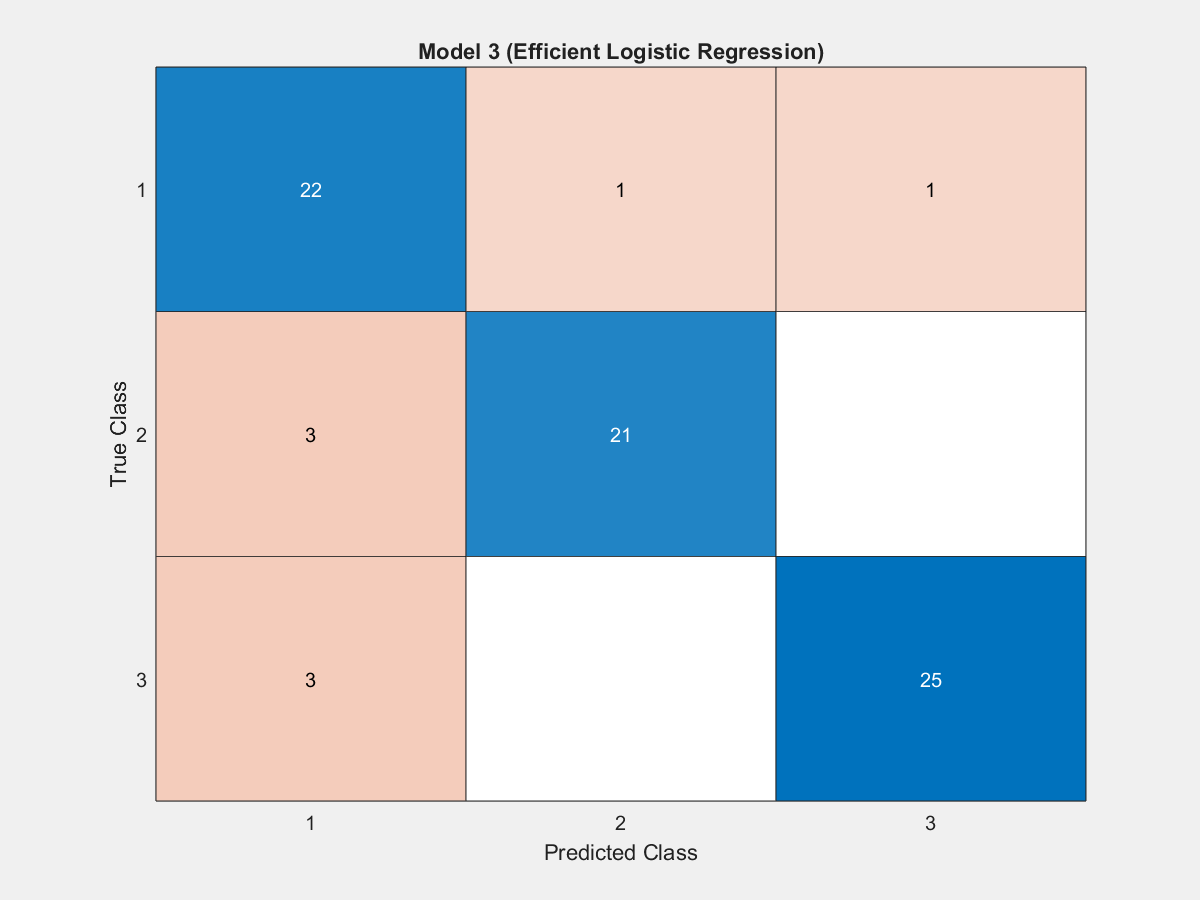

openfig("confusion_matrix.fig", "visible");

- **MODEL EVALUATION**

The next step is to evaluate the model, to do so the 'test' parts are used

% we load the trained classifier
load('trained_eff_log_regression.mat', 'trainedClassifier');

% we predict on the test set using the trained logistic regression classifier
y_pred_test = trainedClassifier.predictFcn(X_test);

%display
confmat_test = confusionmat(y_test, y_pred_test);
disp(confmat_test);  

     6     1     0
     1     4     0
     1     0     7



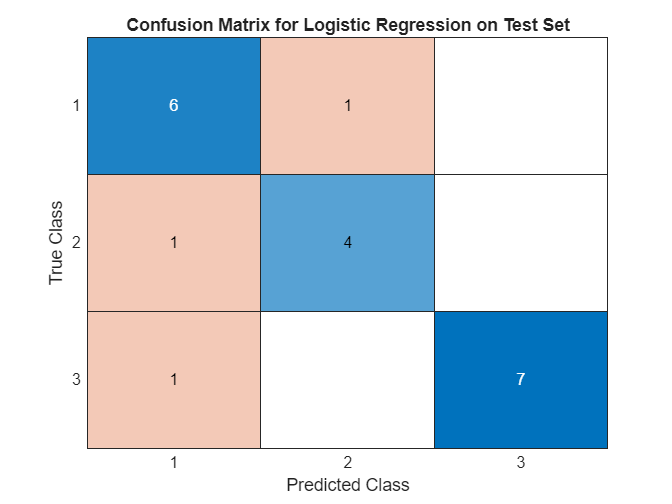


% plot the confusion chart
figure;
confusionchart(confmat_test);
title('Confusion Matrix for Logistic Regression on Test Set');

Now we display some metrics to have a better overview on how the model performs with unseen data

 TP = zeros(3, 1);
 FP = zeros(3, 1);
 TN = zeros(3, 1);
 FN = zeros(3, 1);
 % calculate values
 for i = 1:3
    TP(i) = confmat_test(i,i);
    FP(i) = sum(confmat_test(:, i)) - TP(i);
    FN(i) = sum(confmat_test(i, :)) - TP(i);
    TN(i) = sum(confmat_test(:)) - (TP(i) + FP(i) + FN(i));
 end

 precision_test = mean(TP./(TP + FP))

precision_test = 0.8500


 recall_test = mean(TP./(TP + FN))

recall_test = 0.8440


 f1_test = mean((2*precision_test.*recall_test)./(precision_test + recall_test))

f1_test = 0.8470


  accuracy_test = mean((TP + TN)./sum(confmat_test(:)))

accuracy_test = 0.9000

### Image Correction

% step 1: we ompute dynamic target mean and variance from correctly exposed images
correctly_exposed_paths = filepaths(find(labels == 1));  
correct_means = zeros(numel(correctly_exposed_paths), 1);
correct_vars = zeros(numel(correctly_exposed_paths), 1);

for i = 1:numel(correctly_exposed_paths)
    img = im2double(imread(correctly_exposed_paths{i}));
    img_ycbcr = rgb2ycbcr(img);
    lum = img_ycbcr(:, :, 1);
    correct_means(i) = mean(lum, [1, 2]);
    correct_vars(i) = var(lum, 0, [1, 2]);
end

dynamic_target_mean = mean(correct_means);
dynamic_target_var = mean(correct_vars);

disp(['Dynamic target mean: ', num2str(dynamic_target_mean)]);

Dynamic target mean: 0.49698


disp(['Dynamic target variance: ', num2str(dynamic_target_var)]);

Dynamic target variance: 0.037437


output_folder = "C:\Users\USER\Documents\MATLAB\corrected_images";
features_all = [];  % empty matrix to store features for all images

% check and create output folder if it does not exist
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

files = dir(fullfile(img_dataset, '*.jpg'));
filenames = {files.name}';
filepaths = cellfun(@(s) fullfile(img_dataset, s), filenames, 'UniformOutput', false);


for i = 1:numel(filepaths)
    img = im2double(imread(filepaths{i}));
    
    % check if the image is already correctly exposed (label == 1)
    if labels(i) == 1
        disp(['Skipping gamma correction for correctly exposed image: ', filenames{i}]);
        % we extract features without applying gamma correction
        [~, ~, img_features] = correct_gamma(img, output_folder, filenames{i}, dynamic_target_mean, dynamic_target_var);
    else
        % correct gamma and save corrected image if not correctly exposed
        [img_corrected, y_corrected, img_features] = correct_gamma(img, output_folder, filenames{i}, dynamic_target_mean, dynamic_target_var);
        disp(['Gamma correction applied to: ', filenames{i}]);
    end
    
    
    features_all = [features_all; img_features];

end

Skipping gamma correction for correctly exposed image: 1-01.JPG


Gamma for 1-01.JPG: 1.0353


Gamma for 1-02.JPG: 0.66325


Gamma correction applied to: 1-02.JPG


Gamma for 1-03.JPG: 0.55153


Gamma correction applied to: 1-03.JPG


Skipping gamma correction for correctly exposed image: 10-01.JPG


Gamma for 10-01.JPG: 0.97041


Gamma for 10-02.JPG: 1.4694


Gamma correction applied to: 10-02.JPG


Gamma for 10-03.JPG: 0.42656


Gamma correction applied to: 10-03.JPG


Skipping gamma correction for correctly exposed image: 11-01.JPG


Gamma for 11-01.JPG: 1.2456


Gamma for 11-02.JPG: 1.5945


Gamma correction applied to: 11-02.JPG


Gamma for 11-03.JPG: 0.48738


Gamma correction applied to: 11-03.JPG


Skipping gamma correction for correctly exposed image: 12-01.JPG


Gamma for 12-01.JPG: 1.2054


Gamma for 12-02.JPG: 1.3477


Gamma correction applied to: 12-02.JPG


Gamma for 12-03.JPG: 0.49359


Gamma correction applied to: 12-03.JPG


Skipping gamma correction for correctly exposed image: 13-01.JPG


Gamma for 13-01.JPG: 0.91691


Gamma for 13-02.JPG: 1.2864


Gamma correction applied to: 13-02.JPG


Gamma for 13-03.JPG: 0.38305


Gamma correction applied to: 13-03.JPG


Skipping gamma correction for correctly exposed image: 14-01.JPG


Gamma for 14-01.JPG: 1.1946


Gamma for 14-02.JPG: 1.7597


Gamma correction applied to: 14-02.JPG


Gamma for 14-03.JPG: 0.68117


Gamma correction applied to: 14-03.JPG


Skipping gamma correction for correctly exposed image: 15-01.JPG


Gamma for 15-01.JPG: 1.1615


Gamma for 15-02.JPG: 1.6278


Gamma correction applied to: 15-02.JPG


Gamma for 15-03.JPG: 0.44123


Gamma correction applied to: 15-03.JPG


Skipping gamma correction for correctly exposed image: 16-01.JPG


Gamma for 16-01.JPG: 0.89063


Gamma for 16-02.JPG: 1.8084


Gamma correction applied to: 16-02.JPG


Gamma for 16-03.JPG: 0.51589


Gamma correction applied to: 16-03.JPG


Skipping gamma correction for correctly exposed image: 17-01.JPG


Gamma for 17-01.JPG: 0.68409


Gamma for 17-02.JPG: 1.6581


Gamma correction applied to: 17-02.JPG


Gamma for 17-03.JPG: 0.38505


Gamma correction applied to: 17-03.JPG


Skipping gamma correction for correctly exposed image: 18-01.JPG


Gamma for 18-01.JPG: 1.0033


Gamma for 18-02.JPG: 1.4936


Gamma correction applied to: 18-02.JPG


Gamma for 18-03.JPG: 0.40315


Gamma correction applied to: 18-03.JPG


Skipping gamma correction for correctly exposed image: 19-01.JPG


Gamma for 19-01.JPG: 0.77558


Gamma for 19-02.JPG: 1.559


Gamma correction applied to: 19-02.JPG


Gamma for 19-03.JPG: 0.54061


Gamma correction applied to: 19-03.JPG


Skipping gamma correction for correctly exposed image: 2-01.JPG


Gamma for 2-01.JPG: 1.0859


Gamma for 2-02.JPG: 1.4906


Gamma correction applied to: 2-02.JPG


Gamma for 2-03.JPG: 0.47955


Gamma correction applied to: 2-03.JPG


Skipping gamma correction for correctly exposed image: 20-01.JPG


Gamma for 20-01.JPG: 1.8665


Gamma for 20-02.JPG: 0.65136


Gamma correction applied to: 20-02.JPG


Gamma for 20-03.JPG: 0.52251


Gamma correction applied to: 20-03.JPG


Skipping gamma correction for correctly exposed image: 21-01.JPG


Gamma for 21-01.JPG: 0.97509


Gamma for 21-02.JPG: 1.734


Gamma correction applied to: 21-02.JPG


Gamma for 21-03.JPG: 0.44383


Gamma correction applied to: 21-03.JPG


Skipping gamma correction for correctly exposed image: 22-01.JPG


Gamma for 22-01.JPG: 1.0347


Gamma for 22-02.JPG: 1.8993


Gamma correction applied to: 22-02.JPG


Gamma for 22-03.JPG: 0.46611


Gamma correction applied to: 22-03.JPG


Skipping gamma correction for correctly exposed image: 23-01.JPG


Gamma for 23-01.JPG: 1.21


Gamma for 23-02.JPG: 1.9964


Gamma correction applied to: 23-02.JPG


Gamma for 23-03.JPG: 0.50779


Gamma correction applied to: 23-03.JPG


Skipping gamma correction for correctly exposed image: 24-01.JPG


Gamma for 24-01.JPG: 1.0356


Gamma for 24-02.JPG: 1.1907


Gamma correction applied to: 24-02.JPG


Gamma for 24-03.JPG: 0.45251


Gamma correction applied to: 24-03.JPG


Skipping gamma correction for correctly exposed image: 25-01.JPG


Gamma for 25-01.JPG: 0.99974


Gamma for 25-02.JPG: 1.5858


Gamma correction applied to: 25-02.JPG


Gamma for 25-03.JPG: 0.44811


Gamma correction applied to: 25-03.JPG


Skipping gamma correction for correctly exposed image: 26-01.JPG


Gamma for 26-01.JPG: 0.96151


Gamma for 26-02.JPG: 1.4411


Gamma correction applied to: 26-02.JPG


Gamma for 26-03.JPG: 0.4433


Gamma correction applied to: 26-03.JPG


Skipping gamma correction for correctly exposed image: 27-01.JPG


Gamma for 27-01.JPG: 0.68664


Gamma for 27-02.JPG: 1.632


Gamma correction applied to: 27-02.JPG


Gamma for 27-03.JPG: 0.47922


Gamma correction applied to: 27-03.JPG


Skipping gamma correction for correctly exposed image: 28-01.JPG


Gamma for 28-01.JPG: 0.79658


Gamma for 28-02.JPG: 2.0882


Gamma correction applied to: 28-02.JPG


Gamma for 28-03.JPG: 0.46422


Gamma correction applied to: 28-03.JPG


Skipping gamma correction for correctly exposed image: 29-01.JPG


Gamma for 29-01.JPG: 0.95478


Gamma for 29-02.JPG: 0.9876


Gamma correction applied to: 29-02.JPG


Gamma for 29-03.JPG: 0.47855


Gamma correction applied to: 29-03.JPG


Skipping gamma correction for correctly exposed image: 3-01.JPG


Gamma for 3-01.JPG: 1.182


Gamma for 3-02.JPG: 2.7139


Gamma correction applied to: 3-02.JPG


Gamma for 3-03.JPG: 0.59376


Gamma correction applied to: 3-03.JPG


Skipping gamma correction for correctly exposed image: 30-01.JPG


Gamma for 30-01.JPG: 0.90773


Gamma for 30-02.JPG: 1.3475


Gamma correction applied to: 30-02.JPG


Gamma for 30-03.JPG: 0.49983


Gamma correction applied to: 30-03.JPG


Skipping gamma correction for correctly exposed image: 31-01.JPG


Gamma for 31-01.JPG: 1.1632


Gamma for 31-02.JPG: 1.2198


Gamma correction applied to: 31-02.JPG


Gamma for 31-03.JPG: 0.59047


Gamma correction applied to: 31-03.JPG


Skipping gamma correction for correctly exposed image: 32-01.JPG


Gamma for 32-01.JPG: 0.66178


Gamma for 32-02.JPG: 1.6019


Gamma correction applied to: 32-02.JPG


Gamma for 32-03.JPG: 0.51968


Gamma correction applied to: 32-03.JPG


Skipping gamma correction for correctly exposed image: 4-01.JPG


Gamma for 4-01.JPG: 1.6364


Gamma for 4-02.JPG: 3


Gamma correction applied to: 4-02.JPG


Gamma for 4-03.JPG: 0.7542


Gamma correction applied to: 4-03.JPG


Skipping gamma correction for correctly exposed image: 5-01.JPG


Gamma for 5-01.JPG: 0.57269


Gamma for 5-02.JPG: 1.9089


Gamma correction applied to: 5-02.JPG


Gamma for 5-03.JPG: 0.44858


Gamma correction applied to: 5-03.JPG


Skipping gamma correction for correctly exposed image: 6-01.JPG


Gamma for 6-01.JPG: 1.1402


Gamma for 6-02.JPG: 1.6754


Gamma correction applied to: 6-02.JPG


Gamma for 6-03.JPG: 0.91645


Gamma correction applied to: 6-03.JPG


Skipping gamma correction for correctly exposed image: 7-01.JPG


Gamma for 7-01.JPG: 0.91475


Gamma for 7-02.JPG: 1.6669


Gamma correction applied to: 7-02.JPG


Gamma for 7-03.JPG: 0.47267


Gamma correction applied to: 7-03.JPG


Skipping gamma correction for correctly exposed image: 8-01.JPG


Gamma for 8-01.JPG: 1.4936


Gamma for 8-02.JPG: 2.1212


Gamma correction applied to: 8-02.JPG


Gamma for 8-03.JPG: 0.56298


Gamma correction applied to: 8-03.JPG


Skipping gamma correction for correctly exposed image: 9-01.JPG


Gamma for 9-01.JPG: 0.90659


Gamma for 9-02.JPG: 1.3681


Gamma correction applied to: 9-02.JPG


Gamma for 9-03.JPG: 0.41348


Gamma correction applied to: 9-03.JPG


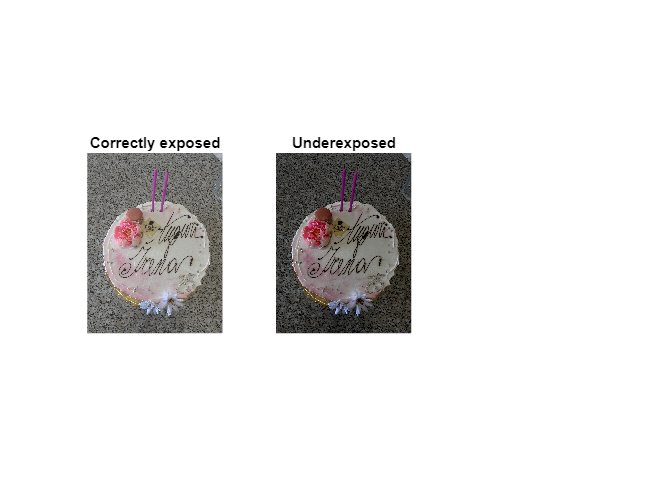

correct = imread("C:\Users\USER\Documents\MATLAB\corrected_images\3-03.JPG");
correct_img1 = im2double(correct);

%comparison
underexposed = imread("C:\Users\USER\Documents\MATLAB\img_dataset\3-03.JPG");
underexposed_img = im2double(underexposed);

figure;
subplot(1, 3, 1), imshow(correct_img1), title("Correctly exposed");
subplot(1, 3, 2), imshow(underexposed_img), title("Underexposed");

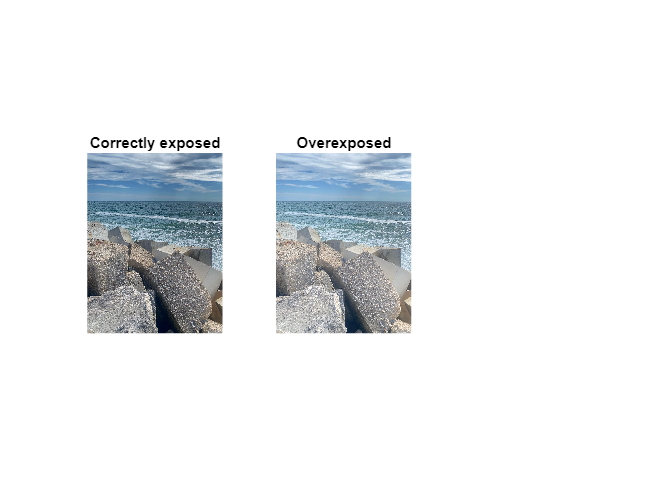

correct = imread("C:\Users\USER\Documents\MATLAB\corrected_images\26-02.JPG");
correct_img2 = im2double(correct);

%comparison
overexposed = imread("C:\Users\USER\Documents\MATLAB\img_dataset\26-02.JPG");
overexposed_img = im2double(overexposed);

figure;
subplot(1, 3, 1), imshow(correct_img2), title("Correctly exposed");
subplot(1, 3, 2), imshow(overexposed_img), title("Overexposed");

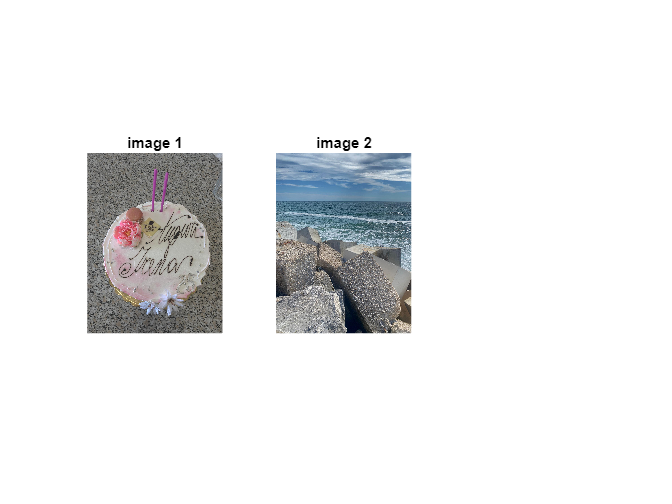


% convert to YCbCr (to get luminance values from Y channel)
img1_ycbcr = rgb2ycbcr(correct_img1);
img2_ycbcr = rgb2ycbcr(correct_img2);

% we get luminance values (Y channel)
lum_norm1 = img1_ycbcr(:, :, 1);
lum_norm2 = img2_ycbcr(:, :, 1);


figure;
subplot(1, 3, 1), imshow(correct_img1), title("image 1");
subplot(1, 3, 2), imshow(correct_img2), title("image 2");

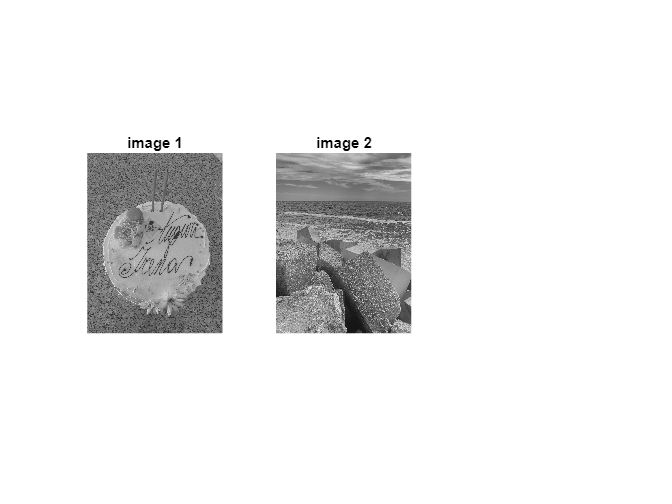

figure;
subplot(1, 3, 1), imshow(lum_norm1), title("image 1");
subplot(1, 3, 2), imshow(lum_norm2), title("image 2");

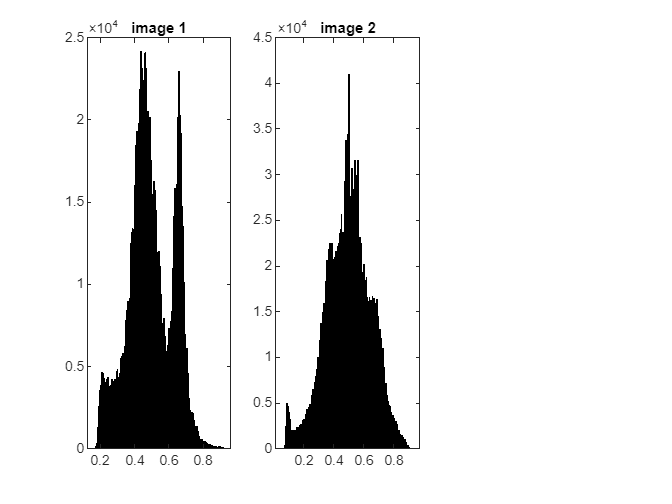

% we plot histograms
figure;
subplot(1, 3, 1), histogram(lum_norm1), title("image 1");
subplot(1, 3, 2), histogram(lum_norm2), title("image 2");

disp(skewness(lum_norm1, 0, [1, 2]));

   -0.0402



disp(skewness(lum_norm2, 0, [1, 2]))

   -0.2023



- **PERFORMANCE TESTING**

% path to the folder
corrected_images_folder = 'C:\Users\USER\Documents\MATLAB\corrected_images';

corrected_files = dir(fullfile(corrected_images_folder, '*.jpg'));
corrected_filenames = {corrected_files.name}';
corrected_filepaths = cellfun(@(s) fullfile(corrected_images_folder, s), corrected_filenames, 'UniformOutput', false);

% store labels
labels_all = zeros(numel(corrected_filepaths), 1);

% label mapping
for i = 1:numel(corrected_filepaths)
    filename = corrected_filenames{i};
    if contains(filename, '-01')
        labels_all(i) = 1;  % correctly exposed
    elseif contains(filename, '-02')
        labels_all(i) = 3;  % overexposed
    elseif contains(filename, '-03')
        labels_all(i) = 2;  % underexposed
    else
        disp(['Warning: Filename does not match expected pattern: ', filename]);
        labels_all(i) = NaN;  % unknown label
    end
end


% dataset creation
 dataset2 = [features_all, labels_all];
 % shuffle to otain a random ordering
 dataset2 = dataset2(randperm(size(dataset2, 1)), :);
 % train-test split
 y_train2 = dataset2(1:end-20, end);
 X_train2 = dataset2(1:end-20, 1:end-1);
 y_test2 = dataset2(end-19:end, end);
 X_test2 = dataset2(end-19:end, 1:end-1);

 % take min and max values for train
 min_vals = min(X_train2, [], 1);
 max_vals = max(X_train2, [], 1);

 X_train2 = (X_train2 - min_vals)./(max_vals - min_vals);
 X_test2 = (X_test2 - min_vals)./(max_vals - min_vals)

X_test2 =     2.0235    0.6354   -0.0067    0.7944    0.3579    0.1001
    0.2442    0.5298    0.3298    0.9922    0.0655    0.1600
    0.0515    0.3668    0.8038    0.5670    0.0288    0.0832
    0.4028    0.6555    0.4488    0.9461    0.1282    0.0566
    0.3844    0.6316    0.5274    0.9618    0.0223    0.1506
    0.1092    0.1292    0.4270    0.3907    0.0957    0.0408
    0.1189    0.2917    0.4022    0.9124    0.0589    0.0289
    0.1086    0.1284    0.4401    0.8742    0.0000    0.0152
    0.0967    0.1985    0.4297    0.7572    0.0681    0.0019
    0.1753    0.3525    0.2627    0.9543    0.0274    0.0635


[trainedClassifier, validationAccuracy] = trainClassifier(X_train2, y_train2);

% we save the trained model to a .mat file to reuse it
save('trained_eff_log_regression.mat', 'trainedClassifier');
disp(validationAccuracy);

    0.6579



% we load the trained classifier
load('trained_eff_log_regression.mat', 'trainedClassifier');

% predict 
y_pred_test2 = trainedClassifier.predictFcn(X_test2);

### Gamma Correction Evaluation

To check whether the gamma correction has worked or not I decided to plot a confusion matrix using the old predicted labels as the true class and the new predicted classes as the predicted class.

The final output in this case shows that the gamma correction works quite well since, all the new predicted classes are labelled as 1, that is, they are classified as 'Correctly Exposed'

% confusion matrix 
new_confmat = confusionmat(y_pred_test, y_pred_test2);
disp(new_confmat);

     3     2     3
     5     0     0
     2     4     1



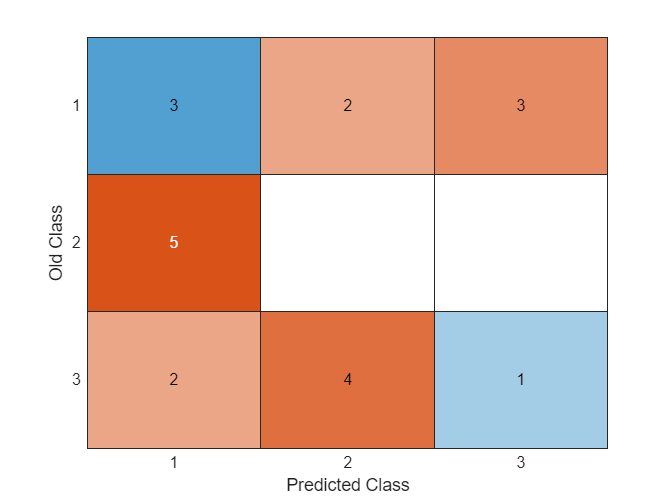

%plot 
figure;
 matrix = confusionchart(new_confmat); matrix.YLabel = 'Old Class';

- **additional evaluation metric:**

To further check gamma correction performances I computed a 80% confidence interval for skewness and I checked whether the histogram distribution looked like a symmatic normal distribution. 

Clarification: skewness is squeezed

% we extract skewness values, 3rd column
skewness_corrimages = features_all(:, 3);

% we calculate the 80% confidence interval for skewness values
lower_bound = prctile(skewness_corrimages, 10);
upper_bound = prctile(skewness_corrimages, 90);

fprintf('The 80%% confidence interval for skewness values is [%.2f, %.2f]\n', lower_bound, upper_bound);

The 80% confidence interval for skewness values is [-0.47, 0.95]


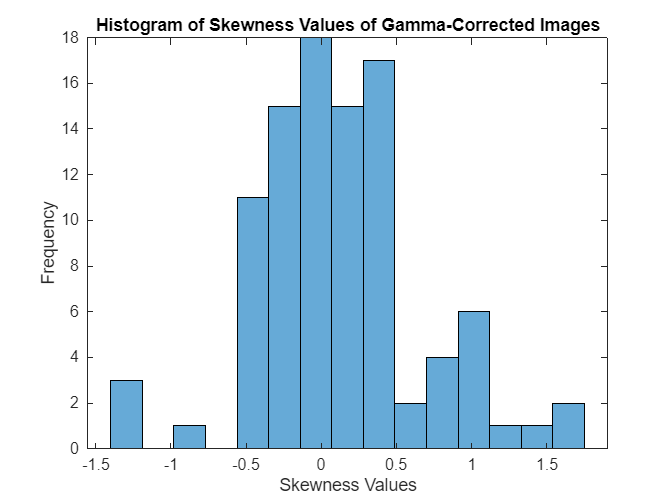

% histogram of skewness values
figure;
histogram(skewness_corrimages, 15); % Adjust the number of bins as needed
xlabel('Skewness Values');
ylabel('Frequency');
title('Histogram of Skewness Values of Gamma-Corrected Images');

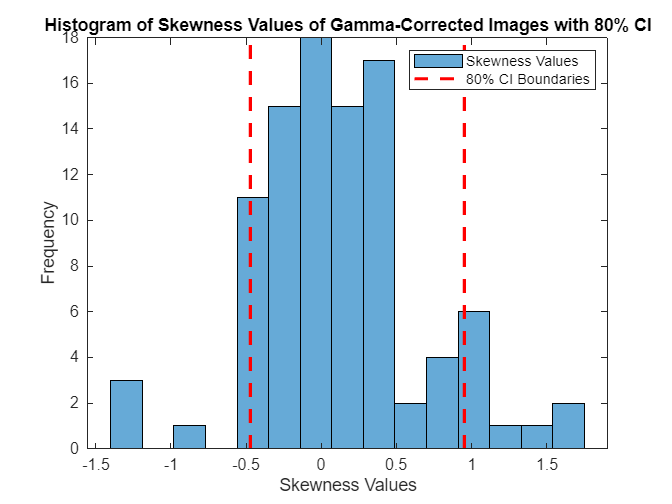

% we create a histogram with 80% CI boundaries
figure;
histogram(skewness_corrimages, 15);
hold on;
% lines
y_limits = ylim;
plot([lower_bound, lower_bound], y_limits, 'r--', 'LineWidth', 2);
plot([upper_bound, upper_bound], y_limits, 'r--', 'LineWidth', 2);
hold off;
xlabel('Skewness Values');
ylabel('Frequency');
title('Histogram of Skewness Values of Gamma-Corrected Images with 80% CI');
legend('Skewness Values', '80% CI Boundaries');


% Calculate and print mean and median of skewness values
mean_skewness = mean(skewness_corrimages);

fprintf('The mean skewness value is %.2f\n', mean_skewness);

The mean skewness value is 0.11


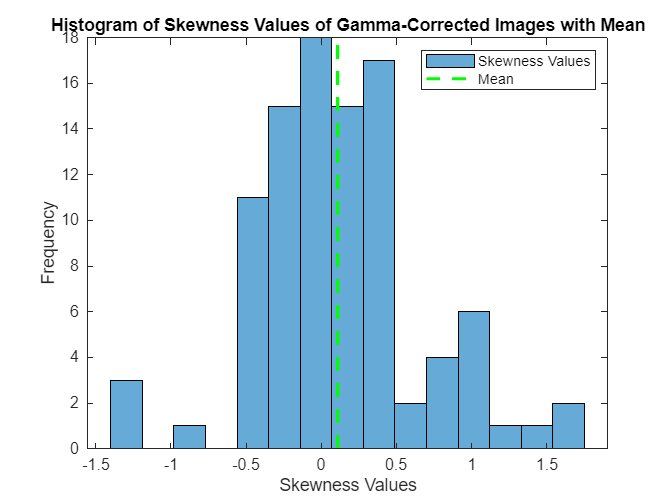


% Create a histogram with mean and median lines
figure;
histogram(skewness_corrimages, 15);
hold on;
% Add lines for the mean and median
y_limits = ylim;
plot([mean_skewness, mean_skewness], y_limits, 'g--', 'LineWidth', 2);
hold off;
xlabel('Skewness Values');
ylabel('Frequency');
title('Histogram of Skewness Values of Gamma-Corrected Images with Mean');
legend('Skewness Values', 'Mean');